# Laboratory activity 4: Longitudinal state–space control of the balancing robot

## 5.1 Simulink model of the balancing robot (longitudinal dynamics only)

% load data and simulink model %
load("balrob_params.mat")

% open simulink model
open_system('nominal_trackingLAURA.slx');

% open simulink model
open_system('nominal_trackingBLACKBOX.slx');

### Matrix Formulation for the Dynamic Model

% body params
l = body.zb;
mb = body.m;
Ibyy = body.Iyy;

% wheel params
w = 2*wheel.yb;
r = wheel.r;
mw = wheel.m;
Iwyy = wheel.Iyy;

% (motor) rotor params
zbrot = mot.rot.zb;
mrot = mot.rot.m;
Irotyy = mot.rot.Iyy;

% gear ratio
n = gbox.N;

% friction params
bw = wheel.B; % wheel viscous fric coeff
bm = mot.B; % motor viscous fric coeff (motor side)
bg = gbox.B; % gbox viscous fric coeff (load side)
b = n^2*bm+bg; % motor+gbox viscous fric coeff (load side)

% inertia matrix
MM = zeros(2,2);

MM(1,1) = 2*Iwyy + 2*Irotyy*n^2 + (mb + 2*(mrot+mw))*r^2;
MM(1,2) = 2*(1-n)*n*Irotyy + r*(l*mb + 2*mrot*zbrot);
MM(2,1) = MM(1,2);
MM(2,2) = Ibyy + 2*(1-n)^2*Irotyy + mb*l^2 + 2*mrot*zbrot^2;

% Coriolis + centrifugal terms matrix
CC = zeros(2,2);

CC(1,1) = 0;
CC(2,1) = 0;
CC(2,2) = 0;
CC(1,2) = -r*(mb*l + 2*mrot*zbrot);

% viscous friction matrix
Fv = zeros(2,2);

Fv(1,1) = 2*(b+bw);
Fv(1,2) = -2*b;
Fv(2,1) = Fv(1,2);
Fv(2,2) = 2*b;

% gravity loading
GG = zeros(2,2);
GG(2,2) = -g*(mb*l + 2*mrot*zbrot);

Fv1 = Fv + (2*n^2*mot.Kt*mot.Ke)/mot.R * [1,-1;-1,1];

## 5.2 Balance–and–position state–space control using LQR methods

### Point 1 - Robot State Estimation 

Tc = 1/(0.35*pi*2);
C = Ts/(Tc + Ts);

% Speed filter
Hw = tf([1,0,0,-1],[3*Ts, 0, 0, 0], Ts);
[numHw, denHw] = tfdata(Hw,'v');

% estimation filter
LPFz = tf([C,0],[1,-(1-C)],Ts);
[numLPFz, denLPFz] = tfdata(LPFz,'v');

### Point 2 - Discrete-time State-space Controller (Nominal)

% system matrices
A = [zeros(2,2), eye(2);  -inv(MM) * GG, -inv(MM) * Fv1]; 
B = (2*n*mot.Kt / mot.R) * [zeros(2,2); inv(MM)] * [1;-1];
H = [1  0  0  0];

% SS data encapulated in a SS object
sysC = ss(A, B, H, 0);
sysD = c2d(sysC, Ts, 'zoh');          
[PHI, GAMMA, H, D] = ssdata(sysD);

% Compute N_x, N_u
S = [PHI-eye(4), GAMMA;  H,   0];
b=[0 0 0 0 1]';

N = linsolve(S,b); %Sx=b
N_x = [N(1:4)'];
N_u = N(5);

% max deviations
gamma_bar = pi/18;
theta_bar = pi/360;
u_bar = 1;

Q = diag([1/(gamma_bar^2)   (1/theta_bar^2)  0  0]);
R = 1/(u_bar^2);
rho = [500,5000];

### Point 3 - Validate the design

#### 1

step_size = 0;
x0 = [0,pi/36,0,0];  
step_disturbance = 0; 

% test #1 - rho = 500
K = dlqr(PHI,GAMMA,Q,R*rho(1));
sim('nominal_trackingLAURA.slx');
data.nominal.test1.rho1.t        = MotorData.time;
data.nominal.test1.rho1.gam      = MotorData.signals(1).values;
data.nominal.test1.rho1.th       = MotorData.signals(2).values;
data.nominal.test1.rho1.dot_gam  = MotorData.signals(3).values;
data.nominal.test1.rho1.dot_th   = MotorData.signals(4).values;

% test #2 - rho = 5000
K = dlqr(PHI,GAMMA,Q,R*rho(2));
sim('nominal_trackingLAURA.slx');
data.nominal.test1.rho2.t        = MotorData.time;
data.nominal.test1.rho2.gam      = MotorData.signals(1).values;
data.nominal.test1.rho2.th       = MotorData.signals(2).values;
data.nominal.test1.rho2.dot_gam  = MotorData.signals(3).values;
data.nominal.test1.rho2.dot_th   = MotorData.signals(4).values;

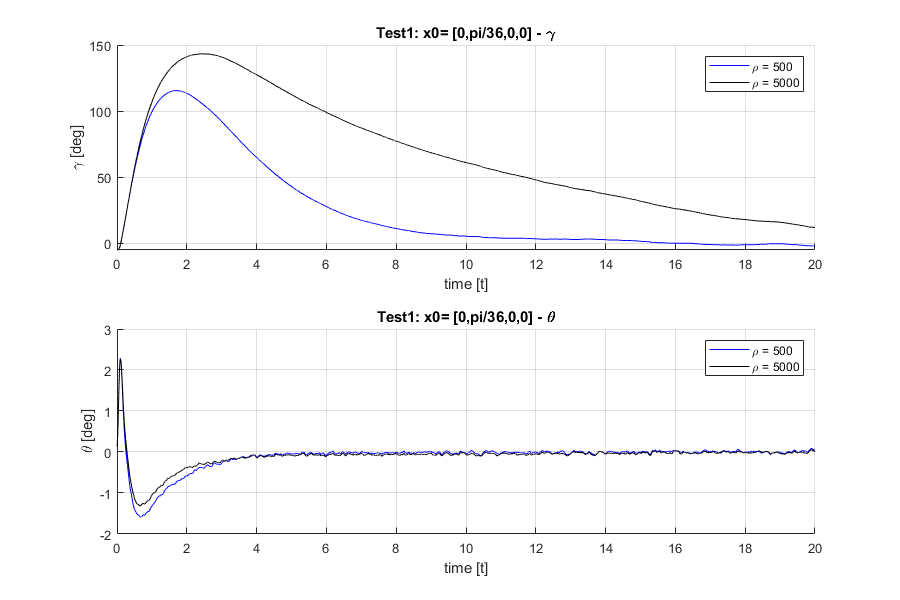

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,1,1);
hold on;
plot(data.nominal.test1.rho1.t, data.nominal.test1.rho1.gam,'b');
plot(data.nominal.test1.rho2.t, data.nominal.test1.rho2.gam,'k');
%plot(data.nominal.test1.rho1.t, data.nominal.test1.rho1.dot_gam,'k');
%plot(data.nominal.test1.rho1.t, data.nominal.test1.rho1.dot_th,'g');

title('Test1: x0= [0,pi/36,0,0] - \gamma')
xlabel('time [t]');
ylabel('\gamma [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;
subplot(2,1,2);
hold on;
plot(data.nominal.test1.rho1.t, data.nominal.test1.rho1.th,'b');
plot(data.nominal.test1.rho2.t, data.nominal.test1.rho2.th,'k');
%plot(data.nominal.test1.rho1.t, data.nominal.test1.rho1.dot_gam,'k');
%plot(data.nominal.test1.rho1.t, data.nominal.test1.rho1.dot_th,'g');

title('Test1: x0= [0,pi/36,0,0] - \theta')
xlabel('time [t]');
ylabel('\theta [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

#### 2

step_size = (0.1/wheel.r)*rad2deg;
x0 = [0,0,0,0];  %initial state
step_disturbance = 0; 

% test #1 - rho = 500
K = dlqr(PHI,GAMMA,Q,R*rho(1));
sim('nominal_trackingLAURA.slx');
data.nominal.test2.rho1.t        = MotorData.time;
data.nominal.test2.rho1.gam      = MotorData.signals(1).values;
data.nominal.test2.rho1.th       = MotorData.signals(2).values;
data.nominal.test2.rho1.dot_gam  = MotorData.signals(3).values;
data.nominal.test2.rho1.dot_th   = MotorData.signals(4).values;

% test #2 - rho = 5000
K = dlqr(PHI,GAMMA,Q,R*rho(2));
sim('nominal_trackingLAURA.slx');
data.nominal.test2.rho2.t        = MotorData.time;
data.nominal.test2.rho2.gam      = MotorData.signals(1).values;
data.nominal.test2.rho2.th       = MotorData.signals(2).values;
data.nominal.test2.rho2.dot_gam  = MotorData.signals(3).values;
data.nominal.test2.rho2.dot_th   = MotorData.signals(4).values;

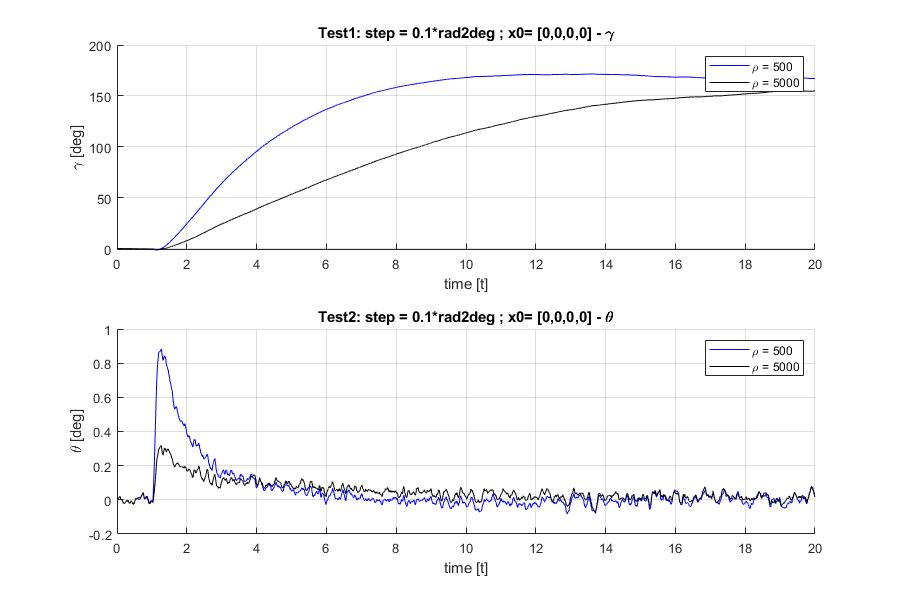

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,1,1);
hold on;
plot(data.nominal.test2.rho1.t, data.nominal.test2.rho1.gam,'b');
plot(data.nominal.test2.rho2.t, data.nominal.test2.rho2.gam,'k');
%plot(data.nominal.test2.rho1.t, data.nominal.test2.rho1.dot_gam,'k');
%plot(data.nominal.test2.rho1.t, data.nominal.test2.rho1.dot_th,'g');

title('Test1: step = 0.1*rad2deg ; x0= [0,0,0,0] - \gamma')
xlabel('time [t]');
ylabel('\gamma [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;
subplot(2,1,2);
hold on;
plot(data.nominal.test2.rho1.t, data.nominal.test2.rho1.th,'b');
plot(data.nominal.test2.rho2.t, data.nominal.test2.rho2.th,'k');
%plot(data.nominal.test2.rho1.t, data.nominal.test2.rho1.dot_gam,'k');
%plot(data.nominal.test2.rho1.t, data.nominal.test2.rho1.dot_th,'g');

title('Test2: step = 0.1*rad2deg ; x0= [0,0,0,0] - \theta')
xlabel('time [t]');
ylabel('\theta [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

#### 3

step_size = (0.1/wheel.r)*rad2deg;
x0 = [0,0,0,0];  %initial state
step_disturbance = 5/drv.duty2V;


% test #1 - rho = 500
K = dlqr(PHI,GAMMA,Q,R*rho(1));
sim('nominal_trackingLAURA.slx');
data.nominal.test3.rho1.t        = MotorData.time;
data.nominal.test3.rho1.gam      = MotorData.signals(1).values;
data.nominal.test3.rho1.th       = MotorData.signals(2).values;
data.nominal.test3.rho1.dot_gam  = MotorData.signals(3).values;
data.nominal.test3.rho1.dot_th   = MotorData.signals(4).values;

% test #2 - rho = 5000
K = dlqr(PHI,GAMMA,Q,R*rho(2));
sim('nominal_trackingLAURA.slx');
data.nominal.test3.rho2.t        = MotorData.time;
data.nominal.test3.rho2.gam      = MotorData.signals(1).values;
data.nominal.test3.rho2.th       = MotorData.signals(2).values;
data.nominal.test3.rho2.dot_gam  = MotorData.signals(3).values;
data.nominal.test3.rho2.dot_th   = MotorData.signals(4).values;

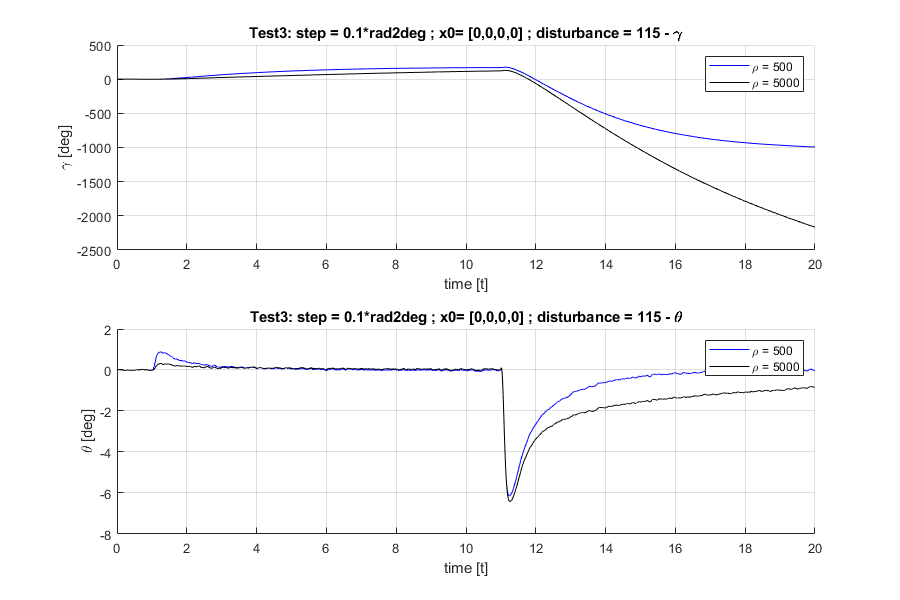

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,1,1);
hold on;
plot(data.nominal.test3.rho1.t, data.nominal.test3.rho1.gam,'b');
plot(data.nominal.test3.rho2.t, data.nominal.test3.rho2.gam,'k');
%plot(data.nominal.test3.rho1.t, data.nominal.test3.rho1.dot_gam,'k');
%plot(data.nominal.test3.rho1.t, data.nominal.test3.rho1.dot_th,'g');

title('Test3: step = 0.1*rad2deg ; x0= [0,0,0,0] ; disturbance = 115 - \gamma')
xlabel('time [t]');
ylabel('\gamma [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;
subplot(2,1,2);
hold on;
plot(data.nominal.test3.rho1.t, data.nominal.test3.rho1.th,'b');
plot(data.nominal.test3.rho2.t, data.nominal.test3.rho2.th,'k');
%plot(data.nominal.test3.rho1.t, data.nominal.test3.rho1.dot_gam,'k');
%plot(data.nominal.test3.rho1.t, data.nominal.test3.rho1.dot_th,'g');

title('Test3: step = 0.1*rad2deg ; x0= [0,0,0,0] ; disturbance = 115 - \theta')
xlabel('time [t]');
ylabel('\theta [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

### Point 4 - Discrete-time State-space Controller (Robust)

%compute extended matrices
zer = zeros(4,1);
Phi_e = [1   ,  H  ;
         zer , PHI];

GAMMA_e = [0 ; GAMMA]; 

H_e = [H , 0];         

% Compute N_x, N_u
q11 = [0.1 , 1]

q11 =     10     1


Q1_e = diag([q11(1)  1/(gamma_bar^2)   (1/theta_bar^2)  0  0]);
Q2_e = diag([q11(2)  1/(gamma_bar^2)   (1/theta_bar^2)  0  0]);

### Point 5 - Validate the design

#### 1

open_system('robust_tracking');

step_size = 0;
x0 = [0,pi/36,0,0];  %initial state
step_disturbance = 0;

% q11 = 0.1

    % test #1 - rho = 500
    K_e = dlqr(Phi_e,GAMMA_e,Q1_e,rho(1)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test1.q1.rho1.t        = MotorData.time;
    data.robust.test1.q1.rho1.gam      = MotorData.signals(1).values;
    data.robust.test1.q1.rho1.th       = MotorData.signals(2).values;
    data.robust.test1.q1.rho1.dot_gam  = MotorData.signals(3).values;
    data.robust.test1.q1.rho1.dot_th   = MotorData.signals(4).values;
    
    % test #2 - rho = 5000
    K_e = dlqr(Phi_e,GAMMA_e,Q1_e,rho(2)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test1.q1.rho2.t        = MotorData.time;
    data.robust.test1.q1.rho2.gam      = MotorData.signals(1).values;
    data.robust.test1.q1.rho2.th       = MotorData.signals(2).values;
    data.robust.test1.q1.rho2.dot_gam  = MotorData.signals(3).values;
    data.robust.test1.q1.rho2.dot_th   = MotorData.signals(4).values;
    
% q11 = 0.1

    % test #1 - rho = 500
    K_e = dlqr(Phi_e,GAMMA_e,Q2_e,rho(1)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test1.q2.rho1.t        = MotorData.time;
    data.robust.test1.q2.rho1.gam      = MotorData.signals(1).values;
    data.robust.test1.q2.rho1.th       = MotorData.signals(2).values;
    data.robust.test1.q2.rho1.dot_gam  = MotorData.signals(3).values;
    data.robust.test1.q2.rho1.dot_th   = MotorData.signals(4).values;
    
    % test #2 - rho = 5000
    K_e = dlqr(Phi_e,GAMMA_e,Q2_e,rho(2)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test1.q2.rho2.t        = MotorData.time;
    data.robust.test1.q2.rho2.gam      = MotorData.signals(1).values;
    data.robust.test1.q2.rho2.th       = MotorData.signals(2).values;
    data.robust.test1.q2.rho2.dot_gam  = MotorData.signals(3).values;
    data.robust.test1.q2.rho2.dot_th   = MotorData.signals(4).values;

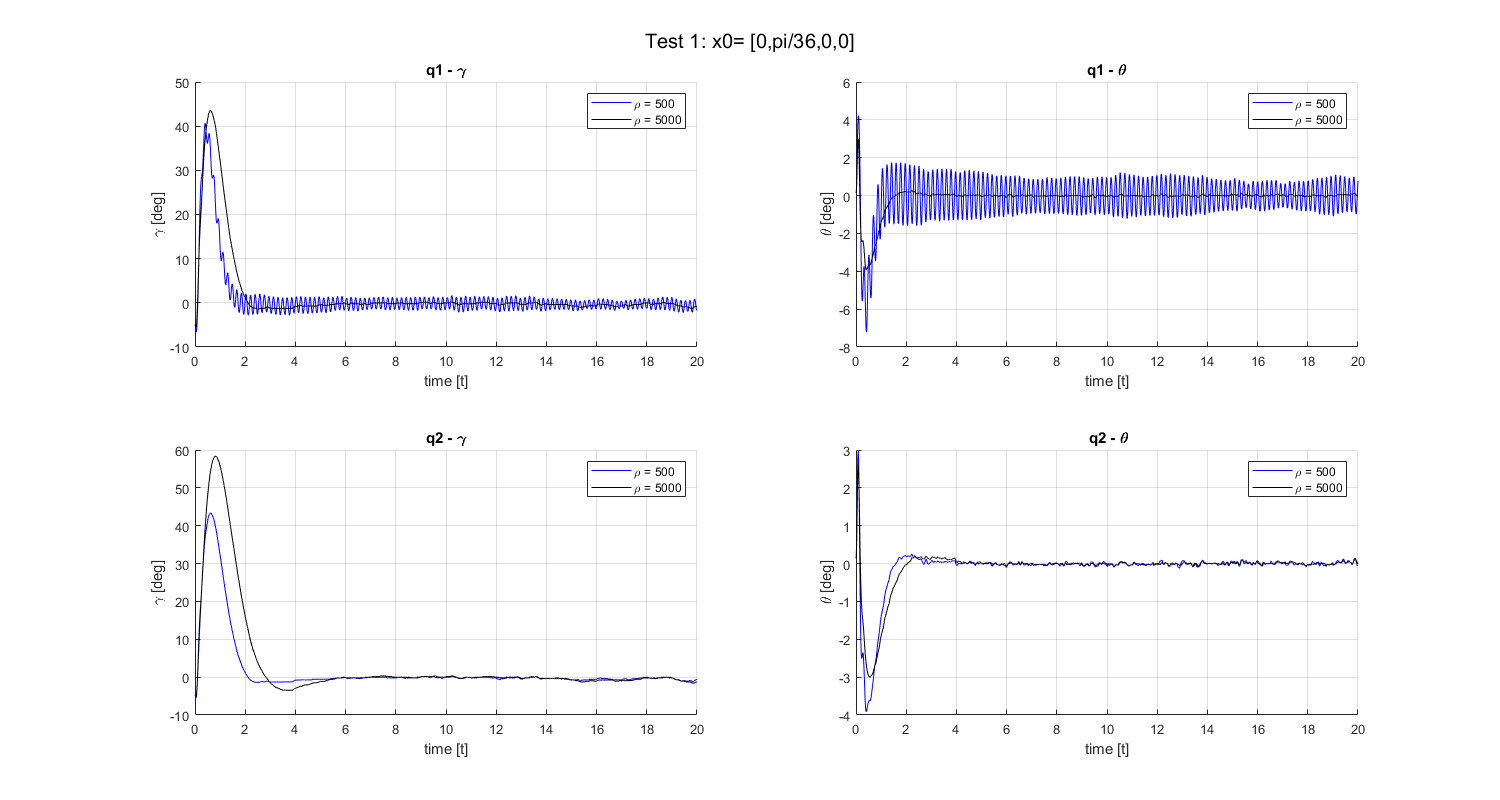

figure('Renderer', 'painters', 'Position', [10 10 1500 800])
subplot(2,2,1);
hold on;
plot(data.robust.test1.q1.rho1.t, data.robust.test1.q1.rho1.gam,'b');
plot(data.robust.test1.q1.rho2.t, data.robust.test1.q1.rho2.gam,'k');
%plot(data.robust.test1.q1.rho1.t, data.robust.test1.q1.rho1.dot_gam,'k');
%plot(data.robust.test1.q1.rho1.t, data.robust.test1.q1.rho1.dot_th,'g');
title('q1 - \gamma')
xlabel('time [t]');
ylabel('\gamma [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

subplot(2,2,2);
hold on;
plot(data.robust.test1.q1.rho1.t, data.robust.test1.q1.rho1.th,'b');
plot(data.robust.test1.q1.rho2.t, data.robust.test1.q1.rho2.th,'k');
%plot(data.robust.test1.q1.rho1.t, data.robust.test1.q1.rho1.dot_gam,'k');
%plot(data.robust.test1.q1.rho1.t, data.robust.test1.q1.rho1.dot_th,'g');
title('q1 - \theta')
xlabel('time [t]');
ylabel('\theta [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

subplot(2,2,3);
hold on;
plot(data.robust.test1.q2.rho1.t, data.robust.test1.q2.rho1.gam,'b');
plot(data.robust.test1.q2.rho2.t, data.robust.test1.q2.rho2.gam,'k');
%plot(data.robust.test1.q2.rho1.t, data.robust.test1.q2.rho1.dot_gam,'k');
%plot(data.robust.test1.q2.rho1.t, data.robust.test1.q2.rho1.dot_th,'g');
title('q2 - \gamma')
xlabel('time [t]');
ylabel('\gamma [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

subplot(2,2,4);
hold on;
plot(data.robust.test1.q2.rho1.t, data.robust.test1.q2.rho1.th,'b');
plot(data.robust.test1.q2.rho2.t, data.robust.test1.q2.rho2.th,'k');
%plot(data.robust.test1.q2.rho1.t, data.robust.test1.q2.rho1.dot_gam,'k');
%plot(data.robust.test1.q2.rho1.t, data.robust.test1.q2.rho1.dot_th,'g');
title(' q2 - \theta')
xlabel('time [t]');
ylabel('\theta [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;
sgtitle('Test 1: x0= [0,pi/36,0,0]') 

#### 2

x0 = [0,0,0,0]; %initial state
step_size = (0.1/wheel.r)*rad2deg;

% q11 = 0.1
    
    % test #1 - rho = 500
    K_e = dlqr(Phi_e,GAMMA_e,Q1_e,rho(1)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test2.q1.rho1.t        = MotorData.time;
    data.robust.test2.q1.rho1.gam      = MotorData.signals(1).values;
    data.robust.test2.q1.rho1.th       = MotorData.signals(2).values;
    data.robust.test2.q1.rho1.dot_gam  = MotorData.signals(3).values;
    data.robust.test2.q1.rho1.dot_th   = MotorData.signals(4).values;
    
    % test #2 - rho = 5000
    K_e = dlqr(Phi_e,GAMMA_e,Q1_e,rho(2)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test2.q1.rho2.t        = MotorData.time;
    data.robust.test2.q1.rho2.gam      = MotorData.signals(1).values;
    data.robust.test2.q1.rho2.th       = MotorData.signals(2).values;
    data.robust.test2.q1.rho2.dot_gam  = MotorData.signals(3).values;
    data.robust.test2.q1.rho2.dot_th   = MotorData.signals(4).values;

% q11 = 1

    % test #1 - rho = 500
    K_e = dlqr(Phi_e,GAMMA_e,Q2_e,rho(1)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test2.q2.rho1.t        = MotorData.time;
    data.robust.test2.q2.rho1.gam      = MotorData.signals(1).values;
    data.robust.test2.q2.rho1.th       = MotorData.signals(2).values;
    data.robust.test2.q2.rho1.dot_gam  = MotorData.signals(3).values;
    data.robust.test2.q2.rho1.dot_th   = MotorData.signals(4).values;
    
    % test #2 - rho = 5000
    K_e = dlqr(Phi_e,GAMMA_e,Q2_e,rho(2)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test2.q2.rho2.t        = MotorData.time;
    data.robust.test2.q2.rho2.gam      = MotorData.signals(1).values;
    data.robust.test2.q2.rho2.th       = MotorData.signals(2).values;
    data.robust.test2.q2.rho2.dot_gam  = MotorData.signals(3).values;
    data.robust.test2.q2.rho2.dot_th   = MotorData.signals(4).values;

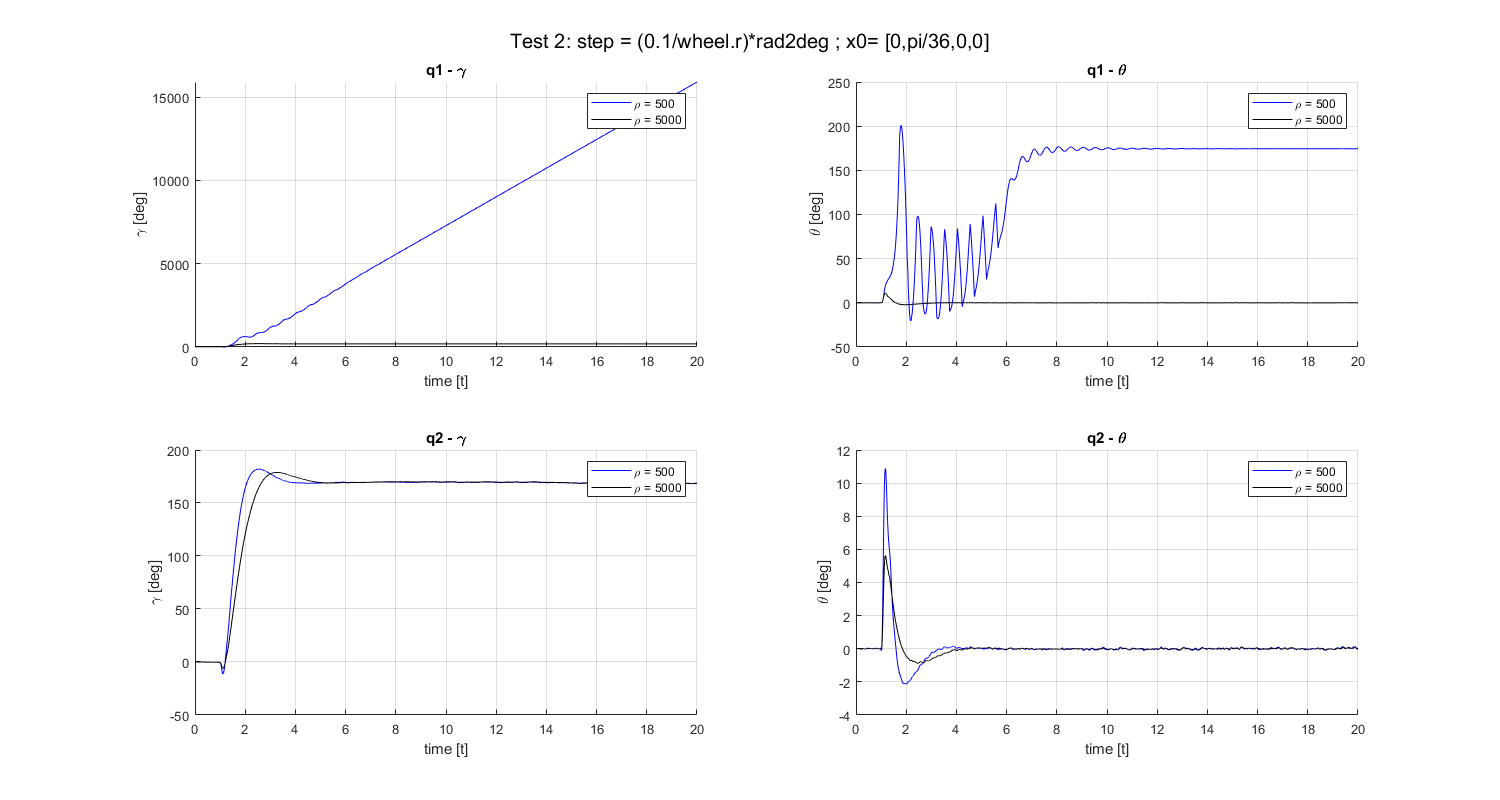

figure('Renderer', 'painters', 'Position', [10 10 1500 800])
subplot(2,2,1);
hold on;
plot(data.robust.test2.q1.rho1.t, data.robust.test2.q1.rho1.gam,'b');
plot(data.robust.test2.q1.rho2.t, data.robust.test2.q1.rho2.gam,'k');
%plot(data.robust.test2.q1.rho1.t, data.robust.test2.q1.rho1.dot_gam,'k');
%plot(data.robust.test2.q1.rho1.t, data.robust.test2.q1.rho1.dot_th,'g');
title('q1 - \gamma')
xlabel('time [t]');
ylabel('\gamma [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

subplot(2,2,2);
hold on;
plot(data.robust.test2.q1.rho1.t, data.robust.test2.q1.rho1.th,'b');
plot(data.robust.test2.q1.rho2.t, data.robust.test2.q1.rho2.th,'k');
%plot(data.robust.test2.q1.rho1.t, data.robust.test2.q1.rho1.dot_gam,'k');
%plot(data.robust.test2.q1.rho1.t, data.robust.test2.q1.rho1.dot_th,'g');
title('q1 - \theta')
xlabel('time [t]');
ylabel('\theta [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

subplot(2,2,3);
hold on;
plot(data.robust.test2.q2.rho1.t, data.robust.test2.q2.rho1.gam,'b');
plot(data.robust.test2.q2.rho2.t, data.robust.test2.q2.rho2.gam,'k');
%plot(data.robust.test2.q2.rho1.t, data.robust.test2.q2.rho1.dot_gam,'k');
%plot(data.robust.test2.q2.rho1.t, data.robust.test2.q2.rho1.dot_th,'g');
title('q2 - \gamma')
xlabel('time [t]');
ylabel('\gamma [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

subplot(2,2,4);
hold on;
plot(data.robust.test2.q2.rho1.t, data.robust.test2.q2.rho1.th,'b');
plot(data.robust.test2.q2.rho2.t, data.robust.test2.q2.rho2.th,'k');
%plot(data.robust.test2.q2.rho1.t, data.robust.test2.q2.rho1.dot_gam,'k');
%plot(data.robust.test2.q2.rho1.t, data.robust.test2.q2.rho1.dot_th,'g');
title('q2 - \theta')
xlabel('time [t]');
ylabel('\theta [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

sgtitle('Test 2: step = (0.1/wheel.r)*rad2deg ; x0= [0,pi/36,0,0]') 

#### 3

step_disturbance =  5/drv.duty2V;  %5/k_duty--V;

% q1 = 0.1
    % test #1 - rho = 500
    K_e = dlqr(Phi_e,GAMMA_e,Q1_e,rho(1)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test3.q1.rho1.t        = MotorData.time;
    data.robust.test3.q1.rho1.gam      = MotorData.signals(1).values;
    data.robust.test3.q1.rho1.th       = MotorData.signals(2).values;
    data.robust.test3.q1.rho1.dot_gam  = MotorData.signals(3).values;
    data.robust.test3.q1.rho1.dot_th   = MotorData.signals(4).values;
    
    % test #2 - rho = 5000
    K_e = dlqr(Phi_e,GAMMA_e,Q1_e,rho(2)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test3.q1.rho2.t        = MotorData.time;
    data.robust.test3.q1.rho2.gam      = MotorData.signals(1).values;
    data.robust.test3.q1.rho2.th       = MotorData.signals(2).values;
    data.robust.test3.q1.rho2.dot_gam  = MotorData.signals(3).values;
    data.robust.test3.q1.rho2.dot_th   = MotorData.signals(4).values;

% q1 = 1
    
    % test #1 - rho = 500
    K_e = dlqr(Phi_e,GAMMA_e,Q2_e,rho(1)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test3.q2.rho1.t        = MotorData.time;
    data.robust.test3.q2.rho1.gam      = MotorData.signals(1).values;
    data.robust.test3.q2.rho1.th       = MotorData.signals(2).values;
    data.robust.test3.q2.rho1.dot_gam  = MotorData.signals(3).values;
    data.robust.test3.q2.rho1.dot_th   = MotorData.signals(4).values;
    
    % test #2 - rho = 5000
    K_e = dlqr(Phi_e,GAMMA_e,Q2_e,rho(2)*R);
    Ki = K_e(1);
    K = [K_e(2) K_e(3) K_e(4) K_e(5)];
    sim('robust_tracking.slx');
    data.robust.test3.q2.rho2.t        = MotorData.time;
    data.robust.test3.q2.rho2.gam      = MotorData.signals(1).values;
    data.robust.test3.q2.rho2.th       = MotorData.signals(2).values;
    data.robust.test3.q2.rho2.dot_gam  = MotorData.signals(3).values;
    data.robust.test3.q2.rho2.dot_th   = MotorData.signals(4).values;

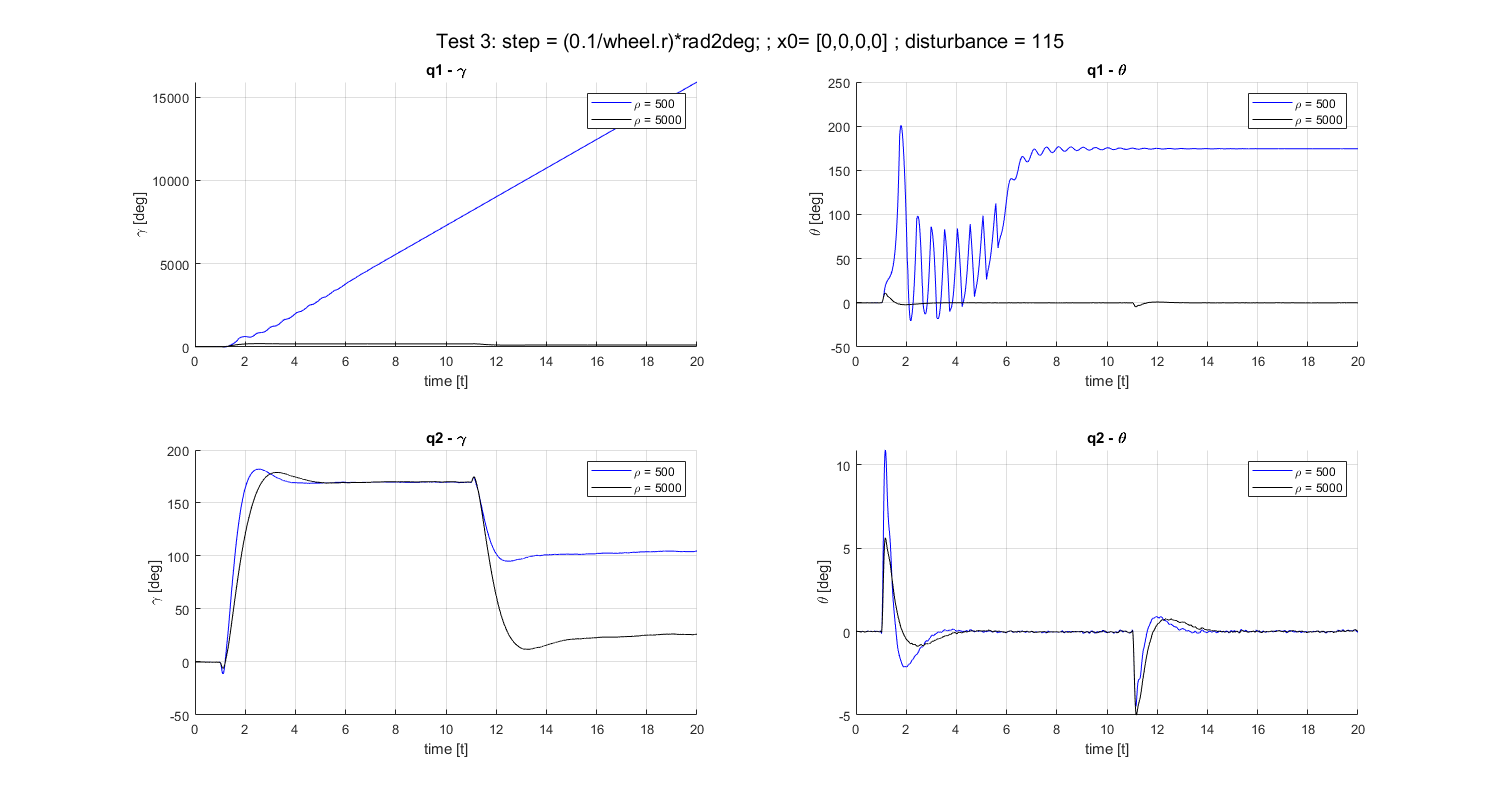

figure('Renderer', 'painters', 'Position', [10 10 1500 800])
subplot(2,2,1);
hold on;
plot(data.robust.test3.q1.rho1.t, data.robust.test3.q1.rho1.gam,'b');
plot(data.robust.test3.q1.rho2.t, data.robust.test3.q1.rho2.gam,'k');
%plot(data.robust.test3.q1.rho1.t, data.robust.test3.q1.rho1.dot_gam,'k');
%plot(data.robust.test3.q1.rho1.t, data.robust.test3.q1.rho1.dot_th,'g');
title('q1 - \gamma')
xlabel('time [t]');
ylabel('\gamma [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

subplot(2,2,2);
hold on;
plot(data.robust.test3.q1.rho1.t, data.robust.test3.q1.rho1.th,'b');
plot(data.robust.test3.q1.rho2.t, data.robust.test3.q1.rho2.th,'k');
%plot(data.robust.test3.q1.rho1.t, data.robust.test3.q1.rho1.dot_gam,'k');
%plot(data.robust.test3.q1.rho1.t, data.robust.test3.q1.rho1.dot_th,'g');
title('q1 - \theta')
xlabel('time [t]');
ylabel('\theta [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

subplot(2,2,3);
hold on;
plot(data.robust.test3.q2.rho1.t, data.robust.test3.q2.rho1.gam,'b');
plot(data.robust.test3.q2.rho2.t, data.robust.test3.q2.rho2.gam,'k');
%plot(data.robust.test3.q2.rho1.t, data.robust.test3.q2.rho1.dot_gam,'k');
%plot(data.robust.test3.q2.rho1.t, data.robust.test3.q2.rho1.dot_th,'g');
title('q2 - \gamma')
xlabel('time [t]');
ylabel('\gamma [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

subplot(2,2,4);
hold on;
plot(data.robust.test3.q2.rho1.t, data.robust.test3.q2.rho1.th,'b');
plot(data.robust.test3.q2.rho2.t, data.robust.test3.q2.rho2.th,'k');
%plot(data.robust.test3.q2.rho1.t, data.robust.test3.q2.rho1.dot_gam,'k');
%plot(data.robust.test3.q2.rho1.t, data.robust.test3.q2.rho1.dot_th,'g');
title('q2 - \theta')
xlabel('time [t]');
ylabel('\theta [deg]');
grid on;
legend('\rho = 500','\rho = 5000')
hold off;

sgtitle('Test 3: step = (0.1/wheel.r)*rad2deg; ; x0= [0,0,0,0] ; disturbance = 115') 